# Fault Diagnosis of Centrifugal Pumps Using Residual Analysis

This example shows a model parity-equations based approach for detection and diagnosis of different types of faults that occur in a pumping system. This example extends the techniques presented in the [Fault Diagnosis of Centrifugal Pumps using Steady State Experiments example](docid:predmaint_ug#mw_1c9f340b-a341-4162-9bb1-d8094591600f) to the situation where data spans multiple operating conditions.

The example follows the centrifugal pump analysis presented in the Fault Diagnosis Applications book by Rolf Isermann [1]. 

## Multi-Speed Pump Runs - Diagnosis by Residual Analysis

The steady-state pump head and torque equations do not produce accurate results if the pump is run at rapidly varying or a wider range of speeds. Friction and other losses could become significant and the model's parameters exhibit dependence on speed. A widely applicable approach in such cases is to create a black box model of the behavior. The parameters of such models need not be physically meaningful. The model is used as a device for simulation of known behaviors. The model's outputs are subtracted from the corresponding measured signals to compute *residuals*. The properties of residuals, such as their mean, variance and power are used to distinguish between normal and faulty operations.

Using the static pump head equation, and the dynamic pump-pipe equations, the 4 residuals as shown in the figure can be computed.

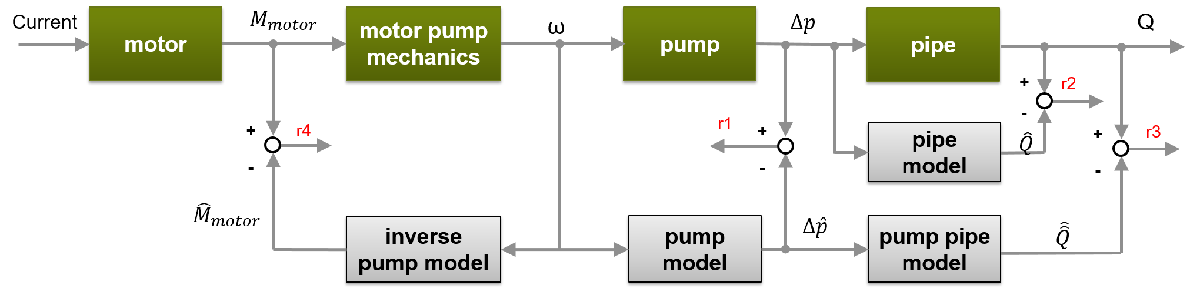

The model has of the following components: 

- Static pump model: $\Delta \hat{p}(t) = \theta_1\omega^2(t) + \theta_2\omega(t)$

- Dynamic pipe model: $\hat{Q}(t) = \theta_3 + \theta_4\sqrt{\Delta p(t)} + \theta_5\hat{Q}(t-1)$

- Dynamic pump-pipe model: $\hat\hat{Q}(t) = \theta_3 + \theta_4\sqrt{\hat{\Delta p(t)}} + \theta_5\hat\hat{Q}(t-1)$

- Dynamic inverse pump model: $\hat{M}_{motor}(t) = \theta_6+\theta_7\omega(t)+\theta_8\omega(t-1)+\theta_9\omega^2(t)+\theta_{10}\hat{M}_{motor}(t-1)$

The model parameters $\theta_1, ... ,\theta_{10} $ show dependence on pump speed. In this example, a piecewise linear approximation for the parameters is computed. Divide the operating region into 3 regimes: 

- 
$$\omega \le 900 \ RPM$$


-  
$$900 < \omega \le 1500 \ RPM$$


- 
$$\omega > 1500 \ RPM$$


A healthy pump was run over a reference speed range of 0 - 3000 RPM in closed loop with a closed-loop controller. The reference input is a modified PRBS signal. The measurements for motor torque, pump torque, speed and pressure were collected at 10 Hz sampling frequency. Load the measured signals and plot the reference and actual pump speeds.

load DynamicOperationData
figure
plot(t, RefSpeed, t, w)
xlabel('Time (s)')
ylabel('Pump Speed (RPM)')
legend('Reference','Actual')

Define operating regimes based on pump speed ranges.

I1 = w<=900;            % first operating regime
I2 = w>900 & w<=1500;   % second operating regime
I3 = w>1500;            % third operating regime

## **Model Identification**

**A. Static Pump Model Identification**

Estimate the parameters $\theta_1$ and $\theta_2$ in the static pump equation using the measured values of pump speed $\omega \left(t\right)$and pressure differential $\Delta p\left(t\right)$ as input-output data. See the helper function `staticPumpEst` that performs this estimation.

th1 = zeros(3,1);  
th2 = zeros(3,1); 
dpest = nan(size(dp));  % estimated pressure difference
[th1(1), th2(1), dpest(I1)] = staticPumpEst(w, dp, I1);  % Theta1, Theta2 estimates for regime 1
[th1(2), th2(2), dpest(I2)] = staticPumpEst(w, dp, I2);  % Theta1, Theta2 estimates for regime 2
[th1(3), th2(3), dpest(I3)] = staticPumpEst(w, dp, I3);  % Theta1, Theta2 estimates for regime 3
plot(t, dp, t, dpest) % compare measured and predicted pressure differential
xlabel('Time (s)')
ylabel('\Delta P')
legend('Measured','Estimated','Location','best')
title('Static Pump Model Validation')

**B. Dynamic Pipe Model Identification**

Estimate the parameters $\theta_3$, $\theta_4$ and $\theta_5$ in the pipe discharge flow equation $\hat{Q}(t) = \theta_3 + \theta_4\sqrt{\Delta p(t)} + \theta_5\hat{Q}(t-1)$, using the measured values of flow rate $Q\left(t\right)$and pressure differential $\Delta p\left(t\right)$ as input-output data. See the helper function `dynamicPipeEst` that performs this estimation.

th3 = zeros(3,1);  
th4 = zeros(3,1); 
th5 = zeros(3,1);
[th3(1), th4(1), th5(1)] = dynamicPipeEst(dp, Q, I1); % Theta3, Theta4, Theta5 estimates for regime 1
[th3(2), th4(2), th5(2)] = dynamicPipeEst(dp, Q, I2); % Theta3, Theta4, Theta5 estimates for regime 2
[th3(3), th4(3), th5(3)] = dynamicPipeEst(dp, Q, I3); % Theta3, Theta4, Theta5 estimates for regime 3

Unlike the static pump model case, the dynamic pipe model shows dynamic dependence on flow rate values. To simulate the model under varying speed regimes, a piecewise-linear model is created in Simulink using the "LPV System" block of Control System Toolbox.  See the Simulink model `LPV_pump_pipe` and the helper function `simulatePumpPipeModel` that performs the simulation.

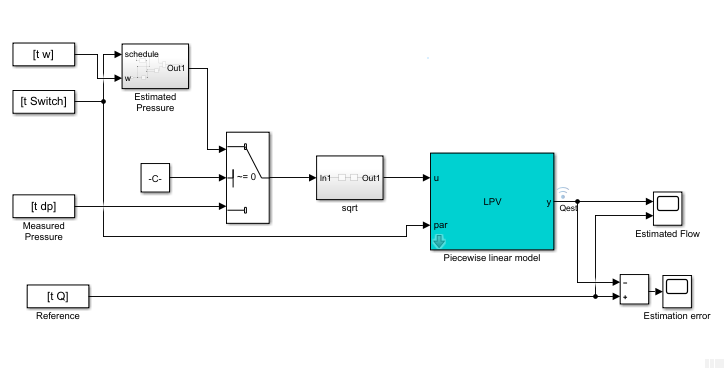

% Check Control System Toolbox availability
ControlsToolboxAvailable = ~isempty(ver('control')) && license('test', 'Control_Toolbox');
if ControlsToolboxAvailable
    % Simulate the dynamic pipe model. Use measured value of pressure as input
    Ts = t(2)-t(1);
    Switch = ones(size(w));
    Switch(I2) = 2;
    Switch(I3) = 3;
    UseEstimatedP = 0;
    Qest_pipe = simulatePumpPipeModel(Ts,th3,th4,th5);
    plot(t,Q,t,Qest_pipe) % compare measured and predicted flow rates
else
    % Load pre-saved simulation results from the piecewise linear Simulink model
    load DynamicOperationData Qest_pipe
    Ts = t(2)-t(1);
    plot(t,Q,t,Qest_pipe)
end
xlabel('Time (s)')
ylabel('Flow rate (Q), m^3/s')
legend('Measured','Estimated','Location','best')
title('Dynamic Pipe Model Validation')

**C. Dynamic Pump Pipe Model Identification**

The Dynamic pump-pipe model uses the same parameters identified above ($\theta_3, \theta_4, \theta_5$) except that the model simulation requires the use of estimated pressure difference rather than the measured one. Hence no new identification is required. Check that the estimated values of $\theta_3, \theta_4, \theta_5$ give a good reproduction of the pump-pipe dynamics.

if ControlsToolboxAvailable
    UseEstimatedP = 1;
    Qest_pump_pipe = simulatePumpPipeModel(Ts,th3,th4,th5);
    plot(t,Q,t,Qest_pump_pipe) % compare measured and predicted flow rates
else
    load DynamicOperationData Qest_pump_pipe 
    plot(t,Q,t,Qest_pump_pipe)
end

xlabel('Time (s)')
ylabel('Flow rate Q (m^3/s)')
legend('Measured','Estimated','location','best')
title('Dynamic Pump-Pipe Model Validation')

The fit is virtually identical to the one obtained using measured pressure values.

**D. Dynamic Inverse Pump Model Identification**

The parameters $\theta_6, ..., \theta_{10}$ can be identified in a similar manner, by regressing the measured torque values on the previous torque and speed measurements. However, a complete multi-speed simulation of the resulting piecewise linear model does not provide a good fit to the data. Hence a different black box modeling approach is tried which involves identifying a Nonlinear ARX model with rational regressors to fit the data.

% Use first 300 samples out of 550 for identification
N = 350;
sys3 = identifyNonlinearARXModel(Mmot,w,Q,Ts,N)
Mmot_est = sim(sys3,[w Q]);
plot(t,Mmot,t,Mmot_est) % compare measured and predicted motor torque
xlabel('Time (s)')
ylabel('Motor Torque (Nm)')
legend('Measured','Estimated','location','best')
title('Inverse pump model validation')

## Residue Generation

Define *residue* of a model as the difference between a measured signal and the corresponding model-produced output. Compute the four residuals corresponding to the four model components. 

r1 = dp - dpest;
r2 = Q - Qest_pipe;
r3 = Q - Qest_pump_pipe;

For computing the inverse pump model residue, apply a smoothing operation on the model output using a moving average filter since the original residues show large variance.

r4 = Mmot - movmean(Mmot_est,[1 5]);

A view of training residues:

figure
subplot(221)
plot(t,r1)
ylabel('Static pump - r1')
subplot(222)
plot(t,r2)
ylabel('Dynamic pipe - r2')
subplot(223)
plot(t,r3)
ylabel('Dynamic pump-pipe - r3')
xlabel('Time (s)')
subplot(224)
plot(t,r4)
ylabel('Dynamic inverse pump - r4')
xlabel('Time (s)')

## Residue Feature Extraction

Residues are signals from which suitable features are extracted for fault isolation. Since no parametric information is available, consider features that are derived purely from signal properties such as maximum amplitude or variance of the signal.

Consider a set of 20 experiments on the pump-pipe system using PRBS input realizations. The experiment set is repeated for each of the following modes:

- Healthy pump

- Fault 1: Wear at clearance gap 

- Fault 2: Small deposits at impeller outlet

- Fault 3: Deposits at impeller inlet

- Fault 4: Abrasive wear at impeller outlet

- Fault 5: Broken blade

- Fault 6: Cavitation

- Fault 7: Speed sensor bias

- Fault 8: Flowmeter bias

- Fault 9: Pressure sensor bias

Load the experimental data

load MultiSpeedOperationData
% Generate operation mode labels
Labels = {'Healthy','ClearanceGapWear','ImpellerOutletDeposit',...
    'ImpellerInletDeposit','AbrasiveWear','BrokenBlade','Cavitation','SpeedSensorBias',...
    'FlowmeterBias','PressureSensorBias'};

Compute residues for each ensemble and each mode of operation. This takes several minutes. Hence the residual data is saved in a data file. Run the `helperComputeEnsembleResidues` to generate the residuals, as in:

% HealthyR = helperComputeEnsembleResidues(HealthyEnsemble,Ts,sys3,th1,th2,th3,th4,th5); % Healthy data residuals

% Load pre-saved data from "helperComputeEnsembleResidues" run
load Residuals

The feature of the residues that would have the most mode-discrimination power is not known a-priori. So generate several candidate features: mean, maximum amplitude, variance, kurtosis and 1-norm for each residual. 

CandidateFeatures = {@mean, @(x)max(abs(x)), @kurtosis, @var, @(x)sum(abs(x))};
FeatureNames = {'Mean','Max','Kurtosis','Variance','OneNorm'};
% generate feature table from gathered residuals of each fault mode
HealthyFeature = helperGenerateFeatureTable(HealthyR, CandidateFeatures, FeatureNames);
Fault1Feature  = helperGenerateFeatureTable(Fault1R,  CandidateFeatures, FeatureNames);
Fault2Feature  = helperGenerateFeatureTable(Fault2R,  CandidateFeatures, FeatureNames);
Fault3Feature  = helperGenerateFeatureTable(Fault3R,  CandidateFeatures, FeatureNames);
Fault4Feature  = helperGenerateFeatureTable(Fault4R,  CandidateFeatures, FeatureNames);
Fault5Feature  = helperGenerateFeatureTable(Fault5R,  CandidateFeatures, FeatureNames);
Fault6Feature  = helperGenerateFeatureTable(Fault6R,  CandidateFeatures, FeatureNames);
Fault7Feature  = helperGenerateFeatureTable(Fault7R,  CandidateFeatures, FeatureNames);
Fault8Feature  = helperGenerateFeatureTable(Fault8R,  CandidateFeatures, FeatureNames);
Fault9Feature  = helperGenerateFeatureTable(Fault9R,  CandidateFeatures, FeatureNames);

There are 20 features in each feature table. Each table contains 50 observations (rows), one from each experiment. 

N = 50; % number of experiments in each mode
FeatureTable = [...
   [HealthyFeature(1:N,:), repmat(Labels(1),[N,1])];...
   [Fault1Feature(1:N,:),  repmat(Labels(2),[N,1])];...
   [Fault2Feature(1:N,:),  repmat(Labels(3),[N,1])];...
   [Fault3Feature(1:N,:),  repmat(Labels(4),[N,1])];...
   [Fault4Feature(1:N,:),  repmat(Labels(5),[N,1])];...
   [Fault5Feature(1:N,:),  repmat(Labels(6),[N,1])];...
   [Fault6Feature(1:N,:),  repmat(Labels(7),[N,1])];...
   [Fault7Feature(1:N,:),  repmat(Labels(8),[N,1])];...
   [Fault8Feature(1:N,:),  repmat(Labels(9),[N,1])];...
   [Fault9Feature(1:N,:),  repmat(Labels(10),[N,1])]];
FeatureTable.Properties.VariableNames{end} = 'Condition';

% Preview some samples of training data
disp(FeatureTable([2 13 37 49 61 62 73 85 102 120],:))

## Classifier Design

**A. Visualizing mode separability using scatter plot **

Begin the analysis by visual inspection of the features. For this, consider Fault 1: Wear at clearance gap. To view which features are most suitable to detect this fault, generate a scatter plot of features with labels 'Healthy' and 'ClearanceGapWear'.

T = FeatureTable(:,1:20);
P = T.Variables;
R = FeatureTable.Condition;
I = strcmp(R,'Healthy') | strcmp(R,'ClearanceGapWear');
f = figure;
gplotmatrix(P(I,:),[],R(I))
f.Position(3:4) = f.Position(3:4)*1.5;

Although not clearly visible, features in columns 9 and 20 provide the most separation. Analyze these features more closely.

f = figure;
Names = FeatureTable.Properties.VariableNames;
fprintf('Selected features for clearance gap fault: %s, %s\n',Names{9},Names{20})
gplotmatrix(P(I,[9 20]),[],R(I))

The plot now clearly shows that features Kurtosis1 and OneNorm4 can be used to separate healthy mode from gap clearance fault mode. A similar analysis can be performed for each fault mode. In all cases, it is possible to find a set of features that distinguish the fault modes. Hence detection of a faulty behavior is always possible. However, fault isolation is more difficult since the same features are affected by multiple fault types. For example, the features Kurtosis1 (Kurtosis of r1) and OneNorm4 (1-norm of r4) show a change for many fault types.  Still some faults such as sensor biases are more easily isolable where the fault is separable in many features.

For the three sensor bias faults, pick features from a manual inspection of the scatter plot.

figure;
I = strcmp(R,'Healthy') | strcmp(R,'PressureSensorBias') | strcmp(R,'SpeedSensorBias') | strcmp(R,'FlowmeterBias');
J = [1 4 5 8 9 12 13 16 17 20]; % selected feature indices
fprintf('Selected features for sensors'' bias: %s\n',strjoin(FeatureTable.Properties.VariableNames(J),', '))
gplotmatrix(P(I,J),[],R(I))

Train a 30 member Tree Bagger classifier for the reduced set of faults (sensor biases only) using a reduced set of features. 

rng(9) % for reproducibility
Mdl = TreeBagger(30, FeatureTable(I,[J 21]), 'Condition',...
   'OOBPrediction','on',...
   'OOBPredictorImportance','on');
figure
plot(oobError(Mdl))
xlabel('Number of trees')
ylabel('Misclassification probability')

The misclassification error is less than 5%. Thus it is possible to pick a smaller set of features for certain subset of faults.

**B. Multi-class Classification using Classification Learner App**

The previous section focused on manual inspection of scatter plots to reduce the feature set for particular fault types. This approach can get tedious and may not cover all fault types. Can you design a classifier that can handle all fault modes in a more automated fashion? There are many classifiers available in Statistics and Machine Learning Toolbox. A quick way to try many of them and compare their performances is to use the Classification Learner App.

- Launch the Classification Learner App and select FeatureTable from workspace as working data for a new session. Set aside 20% of data (10 samples of each mode) for holdout validation. 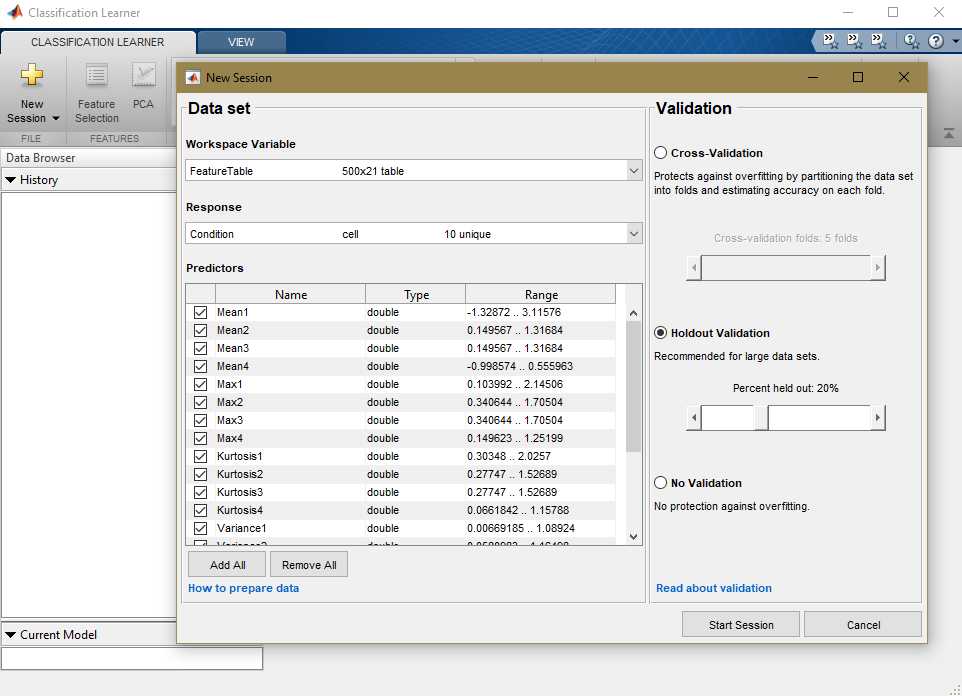

- Select **All** under *Model Type* section of the main tab. Then press the **Train** button. 

- In a short time, about 20 classifiers are trained. Their accuracy are displayed next to their names under the history panel. A Linear Discriminant classifier performs the best, producing 100% accuracy on the hold out samples.

- To get a graphical view of the performance, open a Confusion Matrix plot from the *Plots* section of the main tab. The plot show the performance of the selected classifier (the Linear Discriminant classifier here). 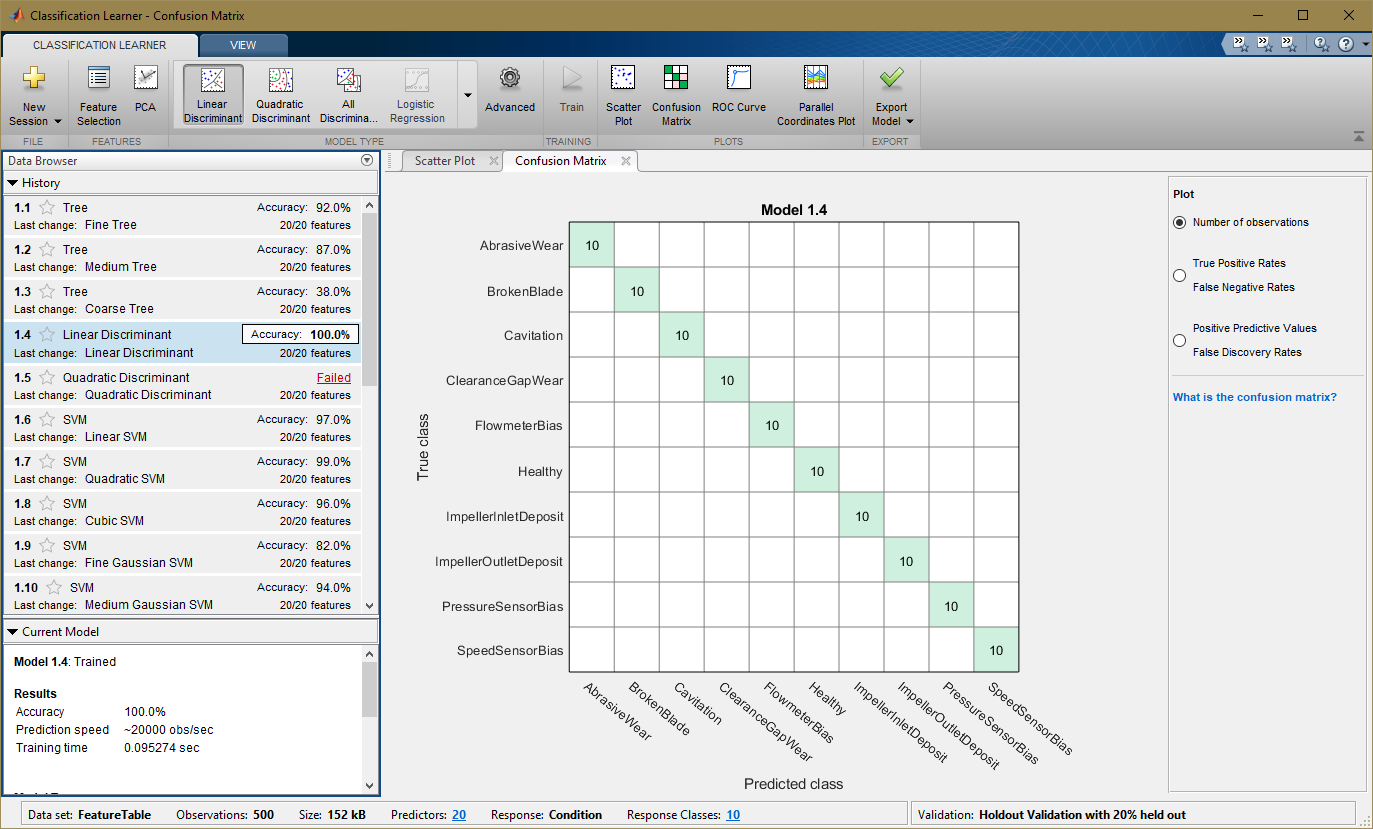

Export the best performing classifier to the workspace and use it for prediction on new measurements.

## Summary

A well designed fault diagnosis strategy can save operating costs by minimizing service downtime and component replacement costs. The strategy benefits from a good knowledge about the operating machine's dynamics which is used in combination with sensor measurements to detect and isolate different kinds of faults. This example described a residual based approach for fault diagnosis of centrifugal pumps. This approach is a good alternative to parameter estimation and tracking based approaches when the modeling task is complex and model parameters show dependence on operating conditions. 

A residual based fault diagnosis approach involves the following steps:

- Model the dynamics between the measurable inputs and outputs of the system using physical considerations or black box system identification techniques.

- Compute residues as difference between measured and model produced signals. The residues may need to be further filtered to improve fault isolability. 

- Extract features such as peak amplitude, power, kurtosis etc from each residual signal. 

- Use features for fault detection and classification using anomaly detection and classification techniques. 

- Not all residues and derived features are sensitive to every fault. A view of feature histograms and scatter plots can reveal which features are suitable for detecting a certain fault type. This process of picking features and assessing their performance for fault isolation can be an iterative procedure.  

## References

- Isermann, Rolf, *Fault-Diagnosis Applications. Model-Based Condition Monitoring: Actuators, Drives, Machinery, Plants, Sensors, and Fault-tolerant System*, Edition 1, Springer-Verlag Berlin Heidelberg, 2011.

## Supporting Functions

Static pump equation parameter estimation

function [x1, x2, dpest] = staticPumpEst(w, dp, I)
%staticPumpEst Static pump parameter estimation in a varying speed setting
% I: sample indices for the selected operating region.

w1 = [0; w(I)];
dp1 = [0; dp(I)];
R1 = [w1.^2 w1];
x = pinv(R1)*dp1;
x1 = x(1);  
x2 = x(2);  

dpest = R1(2:end,:)*x;
end

Dynamic pipe parameter estimation

function [x3, x4, x5, Qest] = dynamicPipeEst(dp, Q, I)
%dynamicPipeEst Dynamic pipe parameter estimation in a varying speed setting
% I: sample indices for the selected operating region.

Q = Q(I);
dp = dp(I);
R1 = [0; Q(1:end-1)];
R2 = dp; R2(R2<0) = 0; R2 = sqrt(R2);
R = [ones(size(R2)), R2, R1];

% Remove out-of-regime samples
ii = find(I);
j = find(diff(ii)~=1);
R = R(2:end,:); R(j,:) = [];
y = Q(2:end); y(j) = [];
x = R\y;

x3 = x(1);
x4 = x(2);
x5 = x(3);

Qest = R*x;
end

Dynamic, multi-operating mode simulation of pump-pipe model using LPV System block.

function Qest = simulatePumpPipeModel(Ts,th3,th4,th5)
%simulatePumpPipeModel Piecewise linear modeling of dynamic pipe system.
% Ts: sample time
% w: Pump rotational speed
% th1, th2, th3 are estimated model parameters for the 3 regimes.
% This function requires Control System Toolbox.

ss1 = ss(th5(1),th4(1),th5(1),th4(1),Ts);
ss2 = ss(th5(2),th4(2),th5(2),th4(2),Ts);
ss3 = ss(th5(3),th4(3),th5(3),th4(3),Ts);
offset = permute([th3(1),th3(2),th3(3)]',[3 2 1]);
OP = struct('Region',[1 2 3]');
sys = cat(3,ss1,ss2,ss3);
sys.SamplingGrid = OP;

assignin('base','sys',sys)
assignin('base','offset',offset)
mdl = 'LPV_pump_pipe';
sim(mdl);
Qest = logsout.get('Qest');
Qest = Qest.Values;
Qest = Qest.Data;
end

Identify a dynamic model for inverse pump dynamics.

function syse = identifyNonlinearARXModel(Mmot,w,Q,Ts,N)
%identifyNonlinearARXModel Identify a nonlinear ARX model for 2-input (w, Q), 1-output (Mmot) data.
% Inputs:
%  w: rotational speed
%  Q: Flow rate
%  Mmot: motor torque
%  N: number of data samples to use
% Outputs:
%  syse: Identified model
%
% This function uses NLARX estimator from System Identification Toolbox.

sys = idnlarx([2 2 1 0 1],'','CustomRegressors',{'u1(t-2)^2','u1(t)*u2(t-2)','u2(t)^2'});
data = iddata(Mmot,[w Q],Ts);
opt = nlarxOptions;
opt.Focus = 'simulation';
opt.SearchOptions.MaxIterations = 500;
syse = nlarx(data(1:N),sys,opt);
end

*Copyright 2017-2018 The MathWorks, Inc.*